LII Model Parameters Based on Lemaire et al.

% Laser-Induced Incandescence (LII) Model
%
% Based on:
% Lemaire, R., Menanteau, S. (2021)
% "Modeling laser-induced incandescence of Diesel soot"
% Applied Physics B, 127:138
% https://doi.org/10.1007/s00340-021-07665-y
%
% This implementation reproduces the base model from the paper.
% No experimental CERL data is included in this repository.

clear; clc;
params.c = 2.998e10; % Speed of Light [cm/s] (Lemaire 2021, Appendix)
params.e_charge = 1.60218e-19; % Electron charge [C] (Lemaire 2021, Appendix)

% Diffusion constants
params.A0_C2 = 9.0235e-4; % [W*cm^-1*K^-1] (Lemaire 2021, Appendix)
params.A0_C3 = 5.7683e-4; % [W*cm^-1*K^-1](Lemaire 2021, Appendix)
params.A1_C2 = 3.8475e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)
params.A1_C3 = 1.8429e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)

params.Bj = NaN; % Sublimation parameter [bar]

% Saturation coefficients
params.B_lambda1_a= NaN; % annealed soot
params.B_lambda1_s= NaN; % unannealed soot
params.B_lambda_n_a= NaN; % annealed
params.B_lambda_n_s= NaN; % unannealed

params.c_a= NaN;   % Annealed soot [J/(g*K)]
params.c_s= NaN;  % Unannealed soot [J/(g*K)]
params.Cabs_multi_a= NaN;   % [cm^2] 
params.Cabs_multi_s= NaN;   % [cm^2]

% Heat capacities
params.Cp_CO= NaN; % Molar heat capacity of CO [J/mol/K]
params.Cp_m= NaN; % Temperature-dependent molar heat capacity [J/mol/K]
params.Cp_O2= NaN; % Molar heat capacity of O2 [J/mol/K]

% Diffusion
params.D_eff= NaN; % Total effective diffusion constant [cm^2/s]
params.D_eff_Cj= NaN; % Effective diffusion constant of Cj clusters [cm^2/s]
params.Dh = @(a) 1.99345 + 0.30224*a - 0.11276*a.^2; % Scaling factor(Lemaire 2021, Appendix)

params.D_HC= NaN;  % Equivalent heat conduction diameter [cm]
params.Dp= NaN; % Primary particle diameter [cm]
params.Dp_ref = 34e-7; % Reference diameter [cm](Lemaire 2021, Appendix)

params.E_m= NaN; % Refractive index function (unannealed)
params.Ea_m= NaN; % Refractive index function (annealed)

params.f= NaN; % Eucken correction factor

params.f1_a= NaN; % Linear absorption scaling (annealed)
params.f1_s= NaN; % Linear absorption scaling (unannealed)

params.fa= NaN; % Absorption empirical scaling (annealed soot)
params.exp= NaN; % Experimental data placeholder
params.F= NaN; % Laser fluence [J/cm^2]

params.hNp= NaN; % Correction factor for multiple scattering
params.hNp_inf= NaN; % Asymptotic correction (large aggregates)
params.J= NaN; % Partial pressure function of Cj clusters

params.ka = @(Tp) 4.935e23 .* exp(-1.255e5 ./ (8.314 .* Tp)); % A-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)
params.kb = @(Tp) 4.935e21 .* exp(-6.352e4 ./ (8.314 .* Tp)); % B-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)

params.kB = 1.381e-23; % Boltzmann constant [J/K]
params.kdiss = @(Tp) 1e18 .* exp(-9.6e5 ./ (8.314 .* Tp)); % pyrolysis rate constant [s^-1](Lemaire 2021, Appendix)

params.kg = @(Tg) 1.0811e-4 + 5.1519e-7 .* Tg;   % [W/cm/K] Thermal Conductivity(Lemaire 2021, Appendix)
params.kh = @(a) 1.04476 + 0.22329*a + 7.14286e-3*a.^2; % Scaling factor for D_HC(Lemaire 2021, Appendix)
params.kim = @(Tp) 1e8 .* exp(-8.3e4 ./ (8.314 .* Tp));   % Interstitial Migration [s^-1](Lemaire 2021, Appendix)

params.kox_a= NaN; % Annealed soot oxidation rate [s^-1*cm^-2]
params.kox_s= NaN; % Unannealed soot oxidation rate [s^-1*cm^-2]
params.kp = 1.38065e-22; % Boltzmann constant in bar*cm^3/K(Lemaire 2021, Appendix)
params.kt = @(Tp) 3.79e27 .* exp(-4.06e5 ./ (8.314 .* Tp)); % Site Transformation [s^-1*cm^-2](Lemaire 2021, Appendix)
params.kvmig = @(Tp) 1.5e17 .* exp(-6.7e5 ./ (8.314 .* Tp)); % Vacancy Migration [s^-1](Lemaire 2021, Appendix)

params.kz = @(Tp) 21.02 .* exp(1.713e4 ./ (8.314 .* Tp)); % Oxide formation [bar^-1](Lemaire 2021, Appendix)
params.k_lambdan_a= NaN; % removal rate of C2 from annealed soot [s^-1]
params.k_lambdan_s= NaN; % removal rate of C2 from unannealed soot [s^-1]
params.me = 9.1095e-35; % electron mass [J*s^2*cm^-2](Lemaire 2021, Appendix)
params.Mg= NaN; % average mass of gas molecules [g]
params.Mp= NaN; % primary particle mass [g]
params.n= NaN; % number of photons absorbed (dimensionless)
params.NA = 6.02214e23; % Avogadro number [mol^-1](Lemaire 2021, Appendix)
params.Nc= NaN; % number of atoms in primary particle
params.Nd= NaN; % number of lattice defects
params.Np= NaN; % number of primary particles per aggregate
params.Ns_a = 3.8e15; % density of carbon atoms (annealed) [cm^-2](Lemaire 2021, Appendix)
params.Ns_s = 2.8e15; % density of carbon atoms (unannealed) [cm^-2](Lemaire 2021, Appendix)
params.Ntot= NaN; % aggregate number density
params.p_Dp= NaN; % PDF of primary particle size
params.p_Np= NaN; % PDF of aggregate size
params.Pdiss= NaN; % effective pressure from photodesorption

params.Peq_Cj= NaN; % thermal equilibrium partial pressure [bar]

params.Pg= NaN; % ambient pressure [bar]
params.PO2 = @(Pg) 0.21*Pg; % O2 partial pressure [bar](Lemaire 2021, Appendix)

params.Pphot= NaN; % instantaneous pressure from photodesorption

params.Pref = 1.01325; % reference pressure [bar](Lemaire 2021, Appendix)

params.Psat_Cj= NaN; % saturation pressure of Cj clusters
params.Psurf_Cj= NaN;% surface pressure of Cj

params.P_lambda_a= NaN;  % effective pressure (annealed soot)
params.P_lambda_s= NaN;  % effective pressure (unannealed soot)

params.q_exp= NaN; % normalized laser irradiance

params.Qabs= NaN; % absorption [W]
params.Qann= NaN; % annealing [W]
params.Qcond_C= NaN; % conduction (continuum) [W]
params.Qcond_FM= NaN; % conduction (free molecular) [W]
params.Qox= NaN; % oxidation [W]
params.Qrad= NaN; % radiation [W]
params.Qsub= NaN; % sublimation [W]
params.Qth= NaN; % thermionic emission [W]

params.R = 8.3145; % universal gas constant [J/mol/K](Lemaire 2021, Appendix)
params.Rdet= NaN; % spectral response of detection system

% Gas constants
params.Rm = 8.3145e7; % [erg*cm^-2*mol^-1*K^-1](Lemaire 2021, Appendix)
params.Rp = 83.145; % [bar*cm^3*mol^-1*K^-1](Lemaire 2021, Appendix)
params.S_LII= NaN; % LII signal [a.u.]

params.t= NaN; % time [s]
params.t_l= NaN; % laser pulse duration [s]
params.T_f_CO = 790; % temperature where CO molecules emit [K](Lemaire 2021, Appendix)
params.Tg= NaN; % ambient gas temperature [K]
params.Tp= NaN; % particle temperature [K]
params.Tref = 0; % reference temperature [K](Lemaire 2021, Appendix)
% Given values: (Lemaire 2021, Appendix)
params.Tc_C1 = 4603.48;
params.Tc_C2 = 4456.59;
params.Tc_C3 = 4136.78;
params.Tc_C4 = 4949.74;
params.Tc_C5 = 4772.87;
params.T_delta= NaN; % limiting sphere temperature (Fuchs model)
params.Uint= NaN;    % internal energy of soot particles [J]
params.Wj = 12.01;   % species weight (C clusters) per j [g/mol](Lemaire 2021, Appendix)
params.WO2 = 31.99; % oxygen molecular weight [g/mol](Lemaire 2021, Appendix)
params.Xa= NaN; % annealed fraction
params.Xd= 1e-2; % defect density (initial)(Lemaire 2021, Appendix)

params.Zox= NaN; % collision rate of O2 with soot surface [s^-1*cm^-2]

% Multi scattering parameters
params.a1= NaN; % parameter for hNp
params.a2= NaN;
params.a3= NaN;

params.alpha_T= NaN; % thermal accommodation coefficient
params.gamma = @(Cp_m) Cp_m ./ (Cp_m - params.R); % Cp/(Cp - R)(Lemaire 2021, Appendix)

params.gamma_j= NaN; % for desorbing species Cj
params.gamma_star= NaN; % mean heat capacity ratio
params.delta= NaN;  % distance between particle and limiting sphere [cm]

% Formation by thermal Sublimation enthalpy
params.dH_sub = @(Tp) -12.326 .* Tp + 8.545e5;   % [J/mol](Lemaire 2021, Appendix)

% Interstitial migration
params.dH_mig = -1.9e4;   % [J/mol](Lemaire 2021, Appendix)

% Vapor species formation enthalpies (C1–C5) (Lemaire 2021, Appendix)
params.dH_C1 = @(Tp) -5.111 .* Tp + 7.266e5;
params.dH_C2 = @(Tp) -12.326 .* Tp + 8.545e5;
params.dH_C3 = @(Tp) -26.921 .* Tp + 8.443e5;
params.dH_C4 = @(Tp) -2.114e-3 .* Tp.^2 - 7.787 .* Tp + 9.811e5;
params.dH_C5 = @(Tp) -2.598e-3 .* Tp.^2 - 7.069 .* Tp + 9.898e5;

% Oxidation enthalpy (Lemaire 2021, Appendix)
params.dH_ox = @(Tp) 2.8901e-14 .* Tp.^5 - 4.9868e-10 .* Tp.^4 + 3.3206e-6 .* Tp.^3 - 1.0307e-2 .* Tp.^2 + 7.9303 .* Tp - 1.1221e5;

% Vacancy migration (Lemaire 2021, Appendix)
params.dH_vmig = -1.4e5; % [J/mol]
% Photodesorption enthalpies
params.dH_lambdan_a = 3.4e5; % annealed soot [J/mol](Lemaire 2021, Appendix)
params.dH_lambdan_s= NaN; % unannealed soot [J/mol] (not given)

params.lambda_det= NaN; % spectral detection range [cm]
params.delta_phi= NaN; % positive charge buildup
params.eta= NaN; % stoichiometric coefficient
params.lambda= NaN; % wavelength [cm]
params.lambda0 = 1; % arbitrary wavelength [cm](Lemaire 2021, Appendix)
params.lambda_c= NaN; % upper boundary wavelength [cm]
params.lambda_l= NaN; % laser excitation wavelength [cm]
params.lambda_g= NaN; % mean free path of gas molecules [cm]
params.lambda_delta= NaN; % mean free path inside limiting sphere [cm]
params.nabla1= NaN;   % function used in Fuchs model
params.nabla2= NaN;   % function used in Fuchs model

params.xi= NaN; % dimensionless parameter for pressure calculation
% Annealed soot density
params.rho_a = @(Tp) 2.6 - 1e-4 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)

% Unannealed soot density
params.rho_s = @(Tp) 2.3031 - 7.3106e-5 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)
params.sigma_j= NaN;  % molecular cross section of sublimed species [cm^2]

params.sigma_n_a= NaN; % cross section for photodesorption (annealed)
params.sigma_n_s= NaN; % cross section for photodesorption (unannealed)
params.phi = 7.37e-19; % [J](Lemaire 2021, Appendix)
params.XA= NaN; % fraction of available A sites
params.Qexp= NaN; % laser spatial domain [cm^2]

Qabs based on Appendix 1 - Lemaire 2021

h = 6.626e-34;
params.Dp = 16.4e-9; % m
params.Np = 125;
params.Tg = 1850; % K
params.lambda_l = 1064e-9; % m
params.F = 0.2; % J/cm^2 laser fluence
params.F = 0.2 * 1e4; % J/m^2
params.t_l = 8e-9; % s pulse duration (Bladh 2008)
params.Xa = 0; % no annealing
params.E_m = 0.23; % refractive index function
params.Ea_m = 0.23; % placeholder since Xa=0
params.B_lambda1_s = 1.15; % J/cm^2 saturation coefficient
params.B_lambda1_a = 1.15; % placeholder
params.B_lambda1_s = 1.15 * 1e4;  % J/m^2
params.B_lambda1_a = 1.15 * 1e4;  % J/m^2
params.hNp = NaN; % calculated later
params.n = 2; % two photon process
params.c_s = 2100;  % J/kg/K (Bladh 2004)
params.c_a = 2100;  % J/kg/K
params.rho_s = @(Tp) (2.3031 - 7.3106e-5 .* Tp) * 1000; % kg/m^3
params.rho_a = @(Tp) (2.6 - 1e-4 .* Tp) * 1000; % kg/m^3
params.c = 2.998e8; % m/s
params.kB = 1.381e-23; % J/K
params.R = 8.3145; % J/mol/K
params.Ntot = 3.46e9; % m^-3
params.Dp_ref = 34e-9; % m
params.lambda0 = 1e-2; % m
c = params.c;

% Unknown parameters:
params.fa = 1;
params.f1_a = 1;
params.f1_s = 1;

Dp   = params.Dp;
lambda_l = params.lambda_l;
F    = params.F;
tl   = params.t_l;

Gaussian temporal profile. I shifted the profile to 3tl. The profile is normalized as well.

t0 = 3 * tl;
q_exp = @(t) exp(-4*log(2)*((t - t0)/tl).^2);
t_test = linspace(0,6*tl,1000);
norm_q = trapz(t_test, q_exp(t_test));
q_exp_norm = @(t) q_exp(t) ./ norm_q;
I = @(t) F .* q_exp_norm(t);

Setup of equations for Qdot_abs, based on equations in Lemaire 2021

Np   = params.Np;
Ntot = params.Ntot;
pNp  = params.p_Np;
pNp = 1;
Xa   = params.Xa;
Em   = params.E_m;
Ea_m = params.Ea_m;
fa   = params.fa;
B1s = params.B_lambda1_s;
B1a = params.B_lambda1_a;
f1s = params.f1_s;
f1a = params.f1_a;
hNp = params.hNp;
n  = params.n;
k_ls = params.k_lambdan_s;
k_la = params.k_lambdan_a;
Nss = params.Ns_s;
Nsa = params.Ns_a;
B_lambdan_s = 0.41e4; % J m^-2 Lemaire 2021
B_lambdan_a = 0.41e4; % J m^-2 assumption same as unannealed
sigma_lambdan_s = 4.2e-16; % n=2
sigma_lambdan_a = 4.2e-16;

alpha1_prime = (1.0209 - 24.0657.*(log((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))./((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))) + 2244.37 * (((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp)).^(-1.5))).^(-1);
alpha2_prime = (0.9871 +2.4878.*(log((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))./((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp)))).^(-1);
hinfNp = 1.11 * alpha1_prime.^2 * Np.^(2*(alpha2_prime - 1));
hNp = hinfNp + (1 - hinfNp) * exp(-(2/3) * (Np -1).^(0.5));
qn_test = q_exp_norm(t_test).^n;
norm_qn = trapz(t_test, qn_test);
k_ls = @(t) (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss) ./ 6) .* (B_lambdan_s.^(-n)) .*(1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_s).^n)));
k_la = @(t) Xa .*(lambda_l ./ (n .* h .* c)) .*((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa) ./ 6) .*(B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp( -((I(t) ./ B_lambdan_a).^n)));
Cabs_multi_s = Ntot * (1 - Xa) * (pi^2 * Dp^3 / lambda_l) * Em * hNp * Np * pNp;
Cabs_multi_a = Ntot * Xa * (pi^2 * Dp^3 / lambda_l) * fa * Ea_m * hNp * Np * pNp;

Qdot_abs = @(t) Cabs_multi_s.*f1s.*B1s.*(1-exp(-(F.*q_exp_norm(t))./B1s)) + Cabs_multi_a.*f1a.*B1a.*(1-exp(-(F.*q_exp_norm(t))./B1a)) + Np.*n.*(h*c/lambda_l).*(k_ls(t)+k_la(t));

Now we will implement the radiation equations

lambda_rad = linspace(200e-9,5000e-9,4000);
Qdot_rad = @(Tp) 8 .* pi .* h .* c.^2 .* trapz( lambda_rad, ((Cabs_multi_s + Cabs_multi_a) ./ (lambda_rad.^5)) .* ( (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* Tp)) - 1)) - (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* params.Tg)) - 1)) ));

Now we will implement conduction free molecular

gamma_star = 1.4; % assumption
params.alpha_T = 0.49; % Lemaire 2021
params.Pg = 101325; % assumption [Pa]
params.Mg = 4.81e-26; % kg assumption
Tdelta = @(Tp) 0.5 .* (Tp + params.Tg); % assumption

if Np == 1
    DHC = Dp;
else 
    DHC = Dp * (Np/params.kh(params.alpha_T)) ^ (1/params.Dh(params.alpha_T));
end

Qcond = @(Tp) (1/8) .* pi .* params.alpha_T .* DHC.^2 .* params.Pg .* sqrt((8 .* params.kB .* Tdelta(Tp)) ./ (pi .* params.Mg)) .* ((gamma_star + 1) ./ (gamma_star - 1)) .* ((Tp ./ Tdelta(Tp)) - 1);

To solve the ODE, in this we consider the equation dU/dt = Qdot_abs and then simplifying that with respect to the equations given in Lemaire 2021.

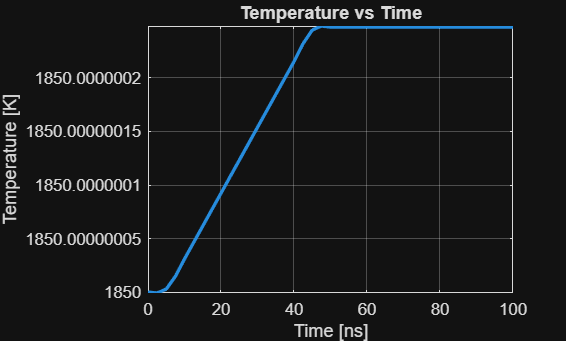

T0 = params.Tg;
rho_s = params.rho_s(T0);
rho_a = params.rho_a(T0);
c_s = params.c_s;
c_a = params.c_a;

tspan = [0 100e-9];
dTpdt = @(t,Tp) (Qdot_abs(t) - Qdot_rad(Tp) - Qcond(Tp)) ./ (Ntot .* Np .* (pi/6) .* Dp.^3 .* (rho_s .* c_s .* (1 - Xa) + rho_a .* c_a .* Xa));
[t,Tp] = ode45(dTpdt,tspan,T0);

figure
plot(t*1e9, Tp, 'LineWidth', 2)
xlabel('Time [ns]')
ylabel('Temperature [K]')
title('Temperature vs Time')
grid on

LII Signal, we use top hat laser profile assumption, so no variation in radial direction.

lambda_det = linspace(600e-9,620e-9,1000); % Lemaire 2026
Rdet = 1; % flat detection assumption
S_LII = zeros(size(Tp));
for i = 1:length(Tp)

    integrand = ((Cabs_multi_s + Cabs_multi_a) ./(lambda_det.^5)) .*((Rdet ./(exp((h*c) ./ (lambda_det .* params.kB .* Tp(i))) - 1))- (Rdet ./ (exp((h*c) ./ (lambda_det .* params.kB .* params.Tg)) - 1)));
    disp(integrand);
    S_LII(i) = 8 .* pi .* h .* c.^2 .*trapz(lambda_det, integrand);
    disp(S_LII(i))

end

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

     0



   1.0e+05 *

   -4.3740   -4.3752   -4.3777   -4.3776   -4.3789   -4.3785   -4.3796   -4.3821   -4.3833   -4.3846   -4.3829   -4.3830   -4.3869   -4.3879   -4.3878   -4.3889   -4.3900   -4.3925   -4.3924   -4.3948   -4.3933   -4.3944   -4.3971   -4.3966   -4.3995   -4.4007   -4.4004   -4.4028   -4.4040   -4.4040   -4.4038   -4.4049   -4.4087   -4.4087   -4.4096   -4.4107   -4.4094   -4.4119   -4.4130   -4.4141   -4.4142   -4.4151   -4.4178   -4.4188   -4.4187   -4.4185   -4.4199   -4.4236   -4.4221   -4.4246   -4.4257   -4.4271   -4.4294   -4.4306   -4.4304   -4.4302   -4.4301   -4.4339   -4.4337   -4.4351   -4.4347   -4.4360   -4.4371   -4.4383   -4.4395   -4.4394   -4.4404   -4.4430   -4.4443   -4.4454   -4.4466   -4.4449   -4.4476   -4.4487   -4.4499   -4.4511   -4.4508   -4.4521   -4.4546   -4.4557   -4.4569   -4.4567   -4.4565   -4.4592   -4.4604   -4.4613   -4.4614   -4.4639   -4.4635   -4.4650   -4.4661   -4.4672   -4.4684   -4.4695   -4.4708   -4.4720   -4.4731   -4.4716   -4.

  -1.4682e-17



   1.0e+06 *

    1.4462    1.4465    1.4468    1.4470    1.4475    1.4477    1.4483    1.4484    1.4489    1.4491    1.4497    1.4499    1.4501    1.4504    1.4509    1.4512    1.4516    1.4518    1.4521    1.4526    1.4528    1.4532    1.4533    1.4539    1.4541    1.4546    1.4549    1.4553    1.4555    1.4559    1.4563    1.4567    1.4568    1.4571    1.4576    1.4578    1.4584    1.4585    1.4589    1.4593    1.4598    1.4600    1.4603    1.4605    1.4611    1.4613    1.4616    1.4618    1.4622    1.4626    1.4630    1.4634    1.4635    1.4639    1.4643    1.4647    1.4650    1.4653    1.4655    1.4661    1.4664    1.4668    1.4670    1.4672    1.4678    1.4681    1.4685    1.4686    1.4691    1.4694    1.4698    1.4702    1.4704    1.4707    1.4712    1.4715    1.4719    1.4722    1.4722    1.4728    1.4730    1.4735    1.4739    1.4742    1.4744    1.4748    1.4752    1.4755    1.4757    1.4762    1.4765    1.4770    1.4773    1.4777    1.4778    1.4780    1.4787    1.4790    1.

   4.8539e-17



   1.0e+06 *

    7.5590    7.5608    7.5625    7.5640    7.5659    7.5678    7.5695    7.5713    7.5729    7.5747    7.5766    7.5784    7.5800    7.5819    7.5835    7.5854    7.5871    7.5887    7.5906    7.5924    7.5941    7.5959    7.5975    7.5995    7.6011    7.6029    7.6046    7.6064    7.6083    7.6099    7.6118    7.6137    7.6151    7.6170    7.6187    7.6205    7.6224    7.6239    7.6258    7.6276    7.6294    7.6313    7.6327    7.6346    7.6363    7.6382    7.6401    7.6415    7.6435    7.6452    7.6470    7.6489    7.6504    7.6523    7.6541    7.6558    7.6577    7.6592    7.6611    7.6629    7.6647    7.6666    7.6684    7.6700    7.6717    7.6735    7.6754    7.6770    7.6788    7.6807    7.6823    7.6842    7.6860    7.6876    7.6895    7.6912    7.6930    7.6950    7.6964    7.6983    7.7001    7.7020    7.7039    7.7053    7.7072    7.7089    7.7108    7.7126    7.7142    7.7161    7.7180    7.7196    7.7215    7.7231    7.7249    7.7268    7.7286    7.7305    7.

   2.5371e-16



   1.0e+07 *

    1.5952    1.5955    1.5959    1.5962    1.5966    1.5970    1.5974    1.5977    1.5981    1.5985    1.5989    1.5992    1.5996    1.6000    1.6003    1.6007    1.6011    1.6014    1.6018    1.6022    1.6026    1.6030    1.6033    1.6037    1.6041    1.6044    1.6048    1.6052    1.6055    1.6059    1.6063    1.6066    1.6070    1.6074    1.6078    1.6081    1.6085    1.6089    1.6093    1.6096    1.6100    1.6104    1.6107    1.6111    1.6115    1.6119    1.6122    1.6126    1.6130    1.6134    1.6137    1.6141    1.6145    1.6148    1.6152    1.6156    1.6160    1.6163    1.6167    1.6171    1.6175    1.6179    1.6182    1.6186    1.6190    1.6193    1.6197    1.6201    1.6204    1.6208    1.6212    1.6216    1.6219    1.6223    1.6227    1.6231    1.6235    1.6238    1.6242    1.6246    1.6249    1.6253    1.6257    1.6261    1.6264    1.6268    1.6272    1.6275    1.6279    1.6283    1.6287    1.6291    1.6294    1.6298    1.6302    1.6306    1.6309    1.6313    1.

   5.3540e-16



   1.0e+07 *

    2.3870    2.3875    2.3881    2.3886    2.3892    2.3897    2.3903    2.3909    2.3914    2.3920    2.3925    2.3931    2.3936    2.3942    2.3948    2.3953    2.3959    2.3964    2.3970    2.3975    2.3981    2.3986    2.3992    2.3997    2.4003    2.4008    2.4014    2.4020    2.4025    2.4031    2.4037    2.4042    2.4047    2.4053    2.4059    2.4064    2.4070    2.4075    2.4081    2.4087    2.4092    2.4098    2.4103    2.4109    2.4115    2.4120    2.4126    2.4131    2.4137    2.4142    2.4148    2.4153    2.4159    2.4165    2.4170    2.4176    2.4181    2.4187    2.4192    2.4198    2.4204    2.4209    2.4215    2.4220    2.4226    2.4232    2.4237    2.4243    2.4248    2.4254    2.4260    2.4265    2.4271    2.4276    2.4282    2.4288    2.4293    2.4299    2.4304    2.4310    2.4316    2.4321    2.4327    2.4332    2.4338    2.4344    2.4349    2.4355    2.4360    2.4366    2.4372    2.4377    2.4383    2.4389    2.4394    2.4400    2.4405    2.4411    2.

   8.0118e-16



   1.0e+07 *

    3.1788    3.1796    3.1803    3.1810    3.1818    3.1825    3.1833    3.1840    3.1847    3.1855    3.1862    3.1870    3.1877    3.1884    3.1892    3.1899    3.1906    3.1914    3.1921    3.1929    3.1936    3.1943    3.1951    3.1958    3.1966    3.1973    3.1981    3.1988    3.1995    3.2003    3.2010    3.2017    3.2025    3.2032    3.2040    3.2047    3.2055    3.2062    3.2069    3.2077    3.2084    3.2092    3.2099    3.2106    3.2114    3.2121    3.2129    3.2136    3.2144    3.2151    3.2158    3.2166    3.2173    3.2181    3.2188    3.2196    3.2203    3.2210    3.2218    3.2225    3.2233    3.2240    3.2248    3.2255    3.2263    3.2270    3.2277    3.2285    3.2292    3.2300    3.2307    3.2315    3.2322    3.2330    3.2337    3.2345    3.2352    3.2360    3.2367    3.2374    3.2382    3.2389    3.2397    3.2404    3.2412    3.2419    3.2427    3.2434    3.2441    3.2449    3.2457    3.2464    3.2472    3.2479    3.2486    3.2494    3.2501    3.2509    3.

   1.0670e-15



   1.0e+07 *

    3.9706    3.9716    3.9725    3.9734    3.9743    3.9753    3.9762    3.9771    3.9780    3.9789    3.9799    3.9808    3.9817    3.9826    3.9836    3.9845    3.9854    3.9863    3.9873    3.9882    3.9891    3.9900    3.9910    3.9919    3.9928    3.9937    3.9947    3.9956    3.9965    3.9974    3.9984    3.9993    4.0002    4.0011    4.0021    4.0030    4.0039    4.0048    4.0058    4.0067    4.0076    4.0086    4.0095    4.0104    4.0113    4.0123    4.0132    4.0141    4.0150    4.0160    4.0169    4.0178    4.0187    4.0197    4.0206    4.0215    4.0225    4.0234    4.0243    4.0253    4.0262    4.0271    4.0280    4.0290    4.0299    4.0308    4.0318    4.0327    4.0336    4.0346    4.0355    4.0364    4.0373    4.0383    4.0392    4.0401    4.0411    4.0420    4.0429    4.0439    4.0448    4.0457    4.0467    4.0476    4.0485    4.0495    4.0504    4.0513    4.0523    4.0532    4.0541    4.0551    4.0560    4.0569    4.0578    4.0588    4.0597    4.0607    4.

   1.3327e-15



   1.0e+07 *

    4.7625    4.7636    4.7647    4.7658    4.7669    4.7680    4.7691    4.7702    4.7713    4.7724    4.7735    4.7747    4.7758    4.7769    4.7780    4.7791    4.7802    4.7813    4.7824    4.7835    4.7846    4.7857    4.7868    4.7880    4.7891    4.7902    4.7913    4.7924    4.7935    4.7946    4.7957    4.7968    4.7979    4.7991    4.8002    4.8013    4.8024    4.8035    4.8046    4.8057    4.8068    4.8079    4.8090    4.8102    4.8113    4.8124    4.8135    4.8146    4.8157    4.8168    4.8179    4.8191    4.8202    4.8213    4.8224    4.8235    4.8246    4.8257    4.8269    4.8280    4.8291    4.8302    4.8313    4.8324    4.8336    4.8347    4.8358    4.8369    4.8380    4.8391    4.8402    4.8414    4.8425    4.8436    4.8447    4.8458    4.8470    4.8481    4.8492    4.8503    4.8514    4.8525    4.8537    4.8548    4.8559    4.8570    4.8581    4.8592    4.8604    4.8615    4.8626    4.8637    4.8648    4.8660    4.8671    4.8682    4.8693    4.8705    4.

   1.5985e-15



   1.0e+07 *

    5.5543    5.5556    5.5569    5.5582    5.5595    5.5607    5.5621    5.5633    5.5646    5.5659    5.5672    5.5685    5.5698    5.5711    5.5724    5.5737    5.5750    5.5762    5.5776    5.5788    5.5801    5.5814    5.5827    5.5840    5.5853    5.5866    5.5879    5.5892    5.5905    5.5918    5.5931    5.5944    5.5957    5.5970    5.5983    5.5996    5.6008    5.6021    5.6034    5.6047    5.6061    5.6073    5.6086    5.6099    5.6112    5.6125    5.6138    5.6151    5.6164    5.6177    5.6190    5.6203    5.6216    5.6229    5.6242    5.6255    5.6268    5.6281    5.6294    5.6307    5.6320    5.6333    5.6346    5.6359    5.6372    5.6385    5.6398    5.6411    5.6424    5.6437    5.6450    5.6463    5.6476    5.6489    5.6502    5.6515    5.6528    5.6541    5.6554    5.6567    5.6580    5.6593    5.6607    5.6620    5.6633    5.6646    5.6659    5.6672    5.6685    5.6698    5.6711    5.6724    5.6737    5.6750    5.6763    5.6776    5.6789    5.6802    5.

   1.8643e-15



   1.0e+07 *

    6.3461    6.3476    6.3491    6.3506    6.3520    6.3535    6.3550    6.3565    6.3579    6.3594    6.3609    6.3624    6.3638    6.3653    6.3668    6.3683    6.3697    6.3712    6.3727    6.3742    6.3757    6.3771    6.3786    6.3801    6.3816    6.3830    6.3845    6.3860    6.3875    6.3889    6.3904    6.3919    6.3934    6.3949    6.3964    6.3978    6.3993    6.4008    6.4023    6.4038    6.4052    6.4067    6.4082    6.4097    6.4112    6.4126    6.4141    6.4156    6.4171    6.4186    6.4201    6.4216    6.4230    6.4245    6.4260    6.4275    6.4290    6.4304    6.4319    6.4334    6.4349    6.4364    6.4379    6.4394    6.4408    6.4423    6.4438    6.4453    6.4468    6.4483    6.4498    6.4513    6.4527    6.4542    6.4557    6.4572    6.4587    6.4602    6.4617    6.4632    6.4647    6.4661    6.4677    6.4691    6.4706    6.4721    6.4736    6.4751    6.4766    6.4781    6.4796    6.4811    6.4826    6.4840    6.4855    6.4870    6.4885    6.4900    6.

   2.1301e-15



   1.0e+07 *

    7.1380    7.1396    7.1413    7.1429    7.1446    7.1463    7.1479    7.1496    7.1512    7.1529    7.1546    7.1562    7.1579    7.1595    7.1612    7.1629    7.1645    7.1662    7.1678    7.1695    7.1712    7.1728    7.1745    7.1762    7.1778    7.1795    7.1811    7.1828    7.1845    7.1861    7.1878    7.1895    7.1911    7.1928    7.1945    7.1961    7.1978    7.1994    7.2011    7.2028    7.2044    7.2061    7.2078    7.2094    7.2111    7.2128    7.2144    7.2161    7.2178    7.2194    7.2211    7.2228    7.2244    7.2261    7.2278    7.2295    7.2311    7.2328    7.2345    7.2361    7.2378    7.2395    7.2412    7.2428    7.2445    7.2462    7.2479    7.2495    7.2512    7.2529    7.2545    7.2562    7.2579    7.2596    7.2612    7.2629    7.2646    7.2663    7.2679    7.2696    7.2713    7.2730    7.2747    7.2763    7.2780    7.2796    7.2814    7.2830    7.2847    7.2864    7.2880    7.2897    7.2914    7.2931    7.2947    7.2964    7.2981    7.2998    7.

   2.3958e-15



   1.0e+07 *

    7.9298    7.9317    7.9335    7.9353    7.9372    7.9390    7.9409    7.9427    7.9445    7.9464    7.9482    7.9501    7.9519    7.9538    7.9556    7.9575    7.9593    7.9611    7.9630    7.9648    7.9667    7.9685    7.9704    7.9722    7.9741    7.9759    7.9778    7.9796    7.9814    7.9833    7.9851    7.9870    7.9888    7.9907    7.9925    7.9944    7.9963    7.9981    7.9999    8.0018    8.0037    8.0055    8.0074    8.0092    8.0111    8.0129    8.0148    8.0166    8.0185    8.0203    8.0222    8.0240    8.0259    8.0277    8.0296    8.0315    8.0333    8.0352    8.0370    8.0389    8.0407    8.0426    8.0444    8.0463    8.0482    8.0500    8.0519    8.0537    8.0556    8.0574    8.0593    8.0612    8.0630    8.0649    8.0667    8.0686    8.0705    8.0723    8.0742    8.0760    8.0779    8.0798    8.0816    8.0835    8.0853    8.0872    8.0891    8.0909    8.0928    8.0947    8.0965    8.0984    8.1003    8.1021    8.1040    8.1058    8.1077    8.1096    8.

   2.6616e-15



   1.0e+08 *

    0.8722    0.8724    0.8726    0.8728    0.8730    0.8732    0.8734    0.8736    0.8738    0.8740    0.8742    0.8744    0.8746    0.8748    0.8750    0.8752    0.8754    0.8756    0.8758    0.8760    0.8762    0.8764    0.8766    0.8768    0.8770    0.8772    0.8774    0.8776    0.8778    0.8780    0.8783    0.8785    0.8787    0.8789    0.8791    0.8793    0.8795    0.8797    0.8799    0.8801    0.8803    0.8805    0.8807    0.8809    0.8811    0.8813    0.8815    0.8817    0.8819    0.8821    0.8823    0.8825    0.8827    0.8829    0.8831    0.8833    0.8835    0.8837    0.8840    0.8842    0.8844    0.8846    0.8848    0.8850    0.8852    0.8854    0.8856    0.8858    0.8860    0.8862    0.8864    0.8866    0.8868    0.8870    0.8872    0.8874    0.8876    0.8878    0.8880    0.8882    0.8885    0.8887    0.8889    0.8891    0.8893    0.8895    0.8897    0.8899    0.8901    0.8903    0.8905    0.8907    0.8909    0.8911    0.8913    0.8915    0.8917    0.8919    0.

   2.9274e-15



   1.0e+08 *

    0.9513    0.9516    0.9518    0.9520    0.9522    0.9525    0.9527    0.9529    0.9531    0.9533    0.9536    0.9538    0.9540    0.9542    0.9544    0.9547    0.9549    0.9551    0.9553    0.9555    0.9558    0.9560    0.9562    0.9564    0.9567    0.9569    0.9571    0.9573    0.9575    0.9578    0.9580    0.9582    0.9584    0.9587    0.9589    0.9591    0.9593    0.9595    0.9598    0.9600    0.9602    0.9604    0.9606    0.9609    0.9611    0.9613    0.9615    0.9618    0.9620    0.9622    0.9624    0.9627    0.9629    0.9631    0.9633    0.9635    0.9638    0.9640    0.9642    0.9644    0.9647    0.9649    0.9651    0.9653    0.9655    0.9658    0.9660    0.9662    0.9664    0.9667    0.9669    0.9671    0.9673    0.9675    0.9678    0.9680    0.9682    0.9684    0.9687    0.9689    0.9691    0.9693    0.9696    0.9698    0.9700    0.9702    0.9705    0.9707    0.9709    0.9711    0.9713    0.9716    0.9718    0.9720    0.9722    0.9725    0.9727    0.9729    0.

   3.1932e-15



   1.0e+08 *

    1.0305    1.0308    1.0310    1.0312    1.0315    1.0317    1.0320    1.0322    1.0324    1.0327    1.0329    1.0332    1.0334    1.0336    1.0339    1.0341    1.0344    1.0346    1.0348    1.0351    1.0353    1.0356    1.0358    1.0360    1.0363    1.0365    1.0368    1.0370    1.0372    1.0375    1.0377    1.0380    1.0382    1.0384    1.0387    1.0389    1.0392    1.0394    1.0396    1.0399    1.0401    1.0404    1.0406    1.0408    1.0411    1.0413    1.0416    1.0418    1.0421    1.0423    1.0425    1.0428    1.0430    1.0433    1.0435    1.0437    1.0440    1.0442    1.0445    1.0447    1.0449    1.0452    1.0454    1.0457    1.0459    1.0462    1.0464    1.0466    1.0469    1.0471    1.0474    1.0476    1.0478    1.0481    1.0483    1.0486    1.0488    1.0491    1.0493    1.0495    1.0498    1.0500    1.0503    1.0505    1.0507    1.0510    1.0512    1.0515    1.0517    1.0520    1.0522    1.0524    1.0527    1.0529    1.0532    1.0534    1.0537    1.0539    1.

   3.4589e-15



   1.0e+08 *

    1.1097    1.1100    1.1102    1.1105    1.1107    1.1110    1.1113    1.1115    1.1118    1.1120    1.1123    1.1126    1.1128    1.1131    1.1133    1.1136    1.1138    1.1141    1.1144    1.1146    1.1149    1.1151    1.1154    1.1156    1.1159    1.1162    1.1164    1.1167    1.1169    1.1172    1.1175    1.1177    1.1180    1.1182    1.1185    1.1188    1.1190    1.1193    1.1195    1.1198    1.1200    1.1203    1.1206    1.1208    1.1211    1.1213    1.1216    1.1219    1.1221    1.1224    1.1226    1.1229    1.1232    1.1234    1.1237    1.1239    1.1242    1.1245    1.1247    1.1250    1.1252    1.1255    1.1258    1.1260    1.1263    1.1265    1.1268    1.1271    1.1273    1.1276    1.1278    1.1281    1.1284    1.1286    1.1289    1.1291    1.1294    1.1297    1.1299    1.1302    1.1304    1.1307    1.1310    1.1312    1.1315    1.1317    1.1320    1.1323    1.1325    1.1328    1.1330    1.1333    1.1336    1.1338    1.1341    1.1343    1.1346    1.1349    1.

   3.7247e-15



   1.0e+08 *

    1.1965    1.1967    1.1970    1.1973    1.1976    1.1978    1.1981    1.1984    1.1987    1.1990    1.1992    1.1995    1.1998    1.2001    1.2003    1.2006    1.2009    1.2012    1.2015    1.2017    1.2020    1.2023    1.2026    1.2029    1.2031    1.2034    1.2037    1.2040    1.2042    1.2045    1.2048    1.2051    1.2054    1.2056    1.2059    1.2062    1.2065    1.2068    1.2070    1.2073    1.2076    1.2079    1.2082    1.2084    1.2087    1.2090    1.2093    1.2096    1.2098    1.2101    1.2104    1.2107    1.2110    1.2112    1.2115    1.2118    1.2121    1.2123    1.2126    1.2129    1.2132    1.2135    1.2138    1.2140    1.2143    1.2146    1.2149    1.2152    1.2154    1.2157    1.2160    1.2163    1.2166    1.2168    1.2171    1.2174    1.2177    1.2180    1.2182    1.2185    1.2188    1.2191    1.2194    1.2196    1.2199    1.2202    1.2205    1.2208    1.2210    1.2213    1.2216    1.2219    1.2222    1.2225    1.2227    1.2230    1.2233    1.2236    1.

   4.0158e-15



   1.0e+08 *

    1.2612    1.2615    1.2618    1.2621    1.2624    1.2627    1.2630    1.2633    1.2636    1.2638    1.2641    1.2644    1.2647    1.2650    1.2653    1.2656    1.2659    1.2662    1.2665    1.2668    1.2671    1.2674    1.2677    1.2680    1.2682    1.2685    1.2688    1.2691    1.2694    1.2697    1.2700    1.2703    1.2706    1.2709    1.2712    1.2715    1.2718    1.2721    1.2724    1.2727    1.2730    1.2732    1.2735    1.2738    1.2741    1.2744    1.2747    1.2750    1.2753    1.2756    1.2759    1.2762    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2791    1.2794    1.2797    1.2800    1.2803    1.2806    1.2809    1.2812    1.2815    1.2818    1.2821    1.2824    1.2827    1.2830    1.2833    1.2836    1.2839    1.2842    1.2845    1.2848    1.2851    1.2854    1.2856    1.2859    1.2862    1.2865    1.2868    1.2871    1.2874    1.2877    1.2880    1.2883    1.2886    1.2889    1.2892    1.2895    1.2898    1.

   4.2332e-15



   1.0e+08 *

    1.2809    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2865    1.2868    1.2871    1.2874    1.2877    1.2880    1.2883    1.2886    1.2889    1.2892    1.2895    1.2898    1.2901    1.2904    1.2907    1.2910    1.2913    1.2916    1.2919    1.2922    1.2925    1.2928    1.2931    1.2934    1.2937    1.2940    1.2943    1.2946    1.2949    1.2952    1.2955    1.2958    1.2961    1.2964    1.2967    1.2970    1.2973    1.2976    1.2979    1.2982    1.2985    1.2988    1.2991    1.2994    1.2997    1.3000    1.3003    1.3006    1.3009    1.3012    1.3015    1.3018    1.3021    1.3024    1.3027    1.3030    1.3033    1.3036    1.3039    1.3042    1.3045    1.3048    1.3051    1.3054    1.3057    1.3060    1.3063    1.3066    1.3069    1.3072    1.3075    1.3078    1.3081    1.3084    1.3087    1.3090    1.3093    1.3096    1.3099    1.

   4.2991e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



   1.0e+08 *

    1.2757    1.2760    1.2763    1.2765    1.2768    1.2771    1.2774    1.2777    1.2780    1.2783    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2858    1.2861    1.2864    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.

   4.2817e-15



S_LII = S_LII ./ max(S_LII);
disp(max(S_LII));

     1



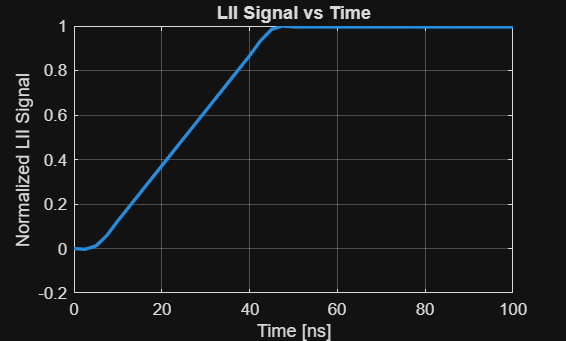

figure
plot(t*1e9,S_LII,'LineWidth',2)

xlabel('Time [ns]')
ylabel('Normalized LII Signal')
title('LII Signal vs Time')

grid on

Peak LII vs Laser Fluence

F_vec = linspace(0.01,3,40) * 1e4;
disp(F_vec);

   1.0e+04 *

    0.0100    0.0867    0.1633    0.2400    0.3167    0.3933    0.4700    0.5467    0.6233    0.7000    0.7767    0.8533    0.9300    1.0067    1.0833    1.1600    1.2367    1.3133    1.3900    1.4667    1.5433    1.6200    1.6967    1.7733    1.8500    1.9267    2.0033    2.0800    2.1567    2.2333    2.3100    2.3867    2.4633    2.5400    2.6167    2.6933    2.7700    2.8467    2.9233    3.0000



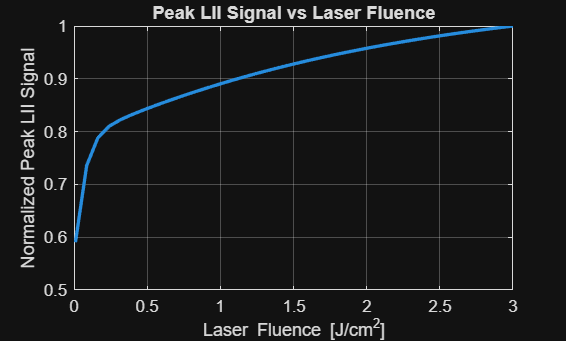

LII_peak = zeros(size(F_vec));

for j = 1:length(F_vec)
    qn_test = q_exp_norm(t_test).^n;
    norm_qn = trapz(t_test, qn_test);

    F_current = F_vec(j);

    I = @(t) F_current .* q_exp_norm(t);
    k_ls = @(t) (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss) ./ 6) .* (B_lambdan_s.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_s).^n)));
    k_la = @(t) Xa .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa) ./ 6) .* (B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_a).^n)));
    Qdot_abs = @(t) Cabs_multi_s.*f1s.*B1s.*(1-exp(-(I(t))./B1s)) + Cabs_multi_a.*f1a.*B1a.*(1-exp(-(I(t))./B1a)) + Np.*n.*(h*c/lambda_l).*(k_ls(t)+k_la(t));

    dTpdt = @(t,Tp) Qdot_abs(t) ./ (Np .* (pi/6) .* Dp.^3 .* (rho_s .* c_s .* (1 - Xa) + rho_a .* c_a .* Xa));

    [t,Tp] = ode45(dTpdt,tspan,T0);

    S_temp = zeros(size(Tp));

    for i = 1:length(Tp)
        integrand = ((Cabs_multi_s + Cabs_multi_a) ./ (lambda_det.^5)) .* ((Rdet ./ (exp((h*c) ./ (lambda_det .* params.kB .* Tp(i))) - 1)) - (Rdet ./ (exp((h*c) ./ (lambda_det .* params.kB .* params.Tg)) - 1)));
        S_temp(i) = 8 .* pi .* h .* c.^2 .* trapz(lambda_det,integrand);
    end
    LII_peak(j) = max(S_temp);
end

LII_peak = LII_peak ./ max(LII_peak);

figure
plot(F_vec./1e4,LII_peak,'LineWidth',2)
xlabel('Laser Fluence [J/cm^2]')
ylabel('Normalized Peak LII Signal')
title('Peak LII Signal vs Laser Fluence')
grid on